clc
close all
% load Lockheed_Jetstar_FC9.mat
run('./aircraft_data_reader.m');

## Define Parameters

U0 = s0(1);
V0 = s0(2);
W0 = s0(3);
p0 = s0(4);
q0  = s0(5);
r0 = s0(6);
phi0 = s0(7);
theta0 = s0(8);
psi0  = s0(9);
x0 = s0(10);
y0 = s0(11);
z0 = s0(12);

## Longitudinal Parameters

XU = SD_Long(1);
ZU = SD_Long(2);
MU = SD_Long(3);
XW = SD_Long(4);
ZW = SD_Long(5);
MW = SD_Long(6);
ZWD = SD_Long(7);
ZQ = SD_Long(8);
MWD = SD_Long(9);
MQ = SD_Long(10);
XDE = SD_Long(11);
ZDE = SD_Long(12);
MDE = SD_Long(13);
XDTH=SD_Long(14);           %thrust
ZDTH = SD_Long(15);         %thrust
MDTH=SD_Long(16);           %thrust

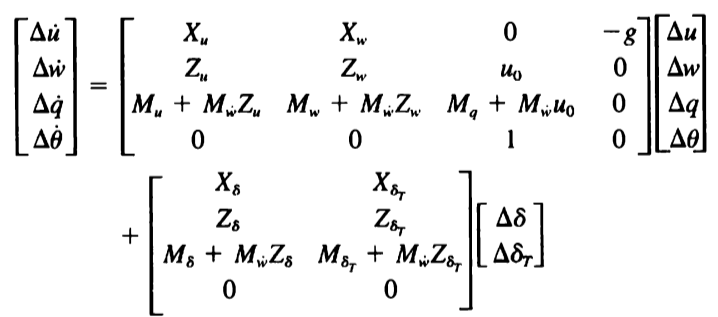

A_longitudinal=[XU,XW,-W0,-g*cos(theta0);...
        ZU/(1-ZWD),ZW/(1-ZWD),(ZQ+U0)/(1-ZWD),-g*sin(theta0)/(1-ZWD);...
        MU+MWD*ZU/(1-ZWD),MW+MWD*ZW/(1-ZWD),MQ+MWD*(ZQ+U0)/(1-ZWD),-MWD*g*sin(theta0)/(1-ZWD);...
        0,0,1,0]

A_longitudinal =    -0.0017    0.0498  -76.6558  -31.9342
   -0.0408   -0.4750  624.3115   -3.9210
    0.0008   -0.0055   -0.5280    0.0009
         0         0    1.0000         0



B_longitudinal=[XDE,XDTH ;...
        ZDE/(1-ZWD),ZDTH/(1-ZWD);...
        MDE+MWD*ZDE/(1-ZWD),MDTH+MWD*ZDTH/(1-ZWD);...
        0,0]

B_longitudinal =     2.6600    0.0008
  -21.7000         0
   -4.2649   -0.0000
         0         0



C_longitudinal=eye(4)

C_longitudinal =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_longitudinal=zeros(4,2)

D_longitudinal =      0     0
     0     0
     0     0
     0     0


SS_Longitudinal = ss(A_longitudinal,B_longitudinal,C_longitudinal,D_longitudinal);
[eig_vectors_long,eig_values_long]= eig(A_longitudinal);
TF_Long = tf(SS_Longitudinal);
time_SP=0:0.01:50;
time_LP=0:0.01:1500;


## Modes Approximation

### Short Period

A_longitudinal_sp = [A_longitudinal(2,2),A_longitudinal(2,3);A_longitudinal(3,2),A_longitudinal(3,3)]

A_longitudinal_sp =    -0.4750  624.3115
   -0.0055   -0.5280


B_longitudinal_sp = [B_longitudinal(2,1),B_longitudinal(2,2);B_longitudinal(3,1),B_longitudinal(3,2)]

B_longitudinal_sp =   -21.7000         0
   -4.2649   -0.0000


C_longitudinal_sp = eye(2)

C_longitudinal_sp =      1     0
     0     1


D_longitudinal_sp = zeros(2,2)

D_longitudinal_sp =      0     0
     0     0


SS_sp = ss(A_longitudinal_sp,B_longitudinal_sp,C_longitudinal_sp,D_longitudinal_sp);  % state space for short period
[eig_vectors_sp,eig_values_sp]= eig(A_longitudinal_sp)

eig_vectors_sp =    1.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0000 + 0.0030i  -0.0000 - 0.0030i


eig_values_sp =   -0.5015 + 1.8524i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5015 - 1.8524i


char_eq_sp=poly([eig_values_sp(1,1),eig_values_sp(2,2)]);
Wn_longitudial_sp_apx = sqrt(char_eq_sp(3))

Wn_longitudial_sp_apx = 1.9191

Zeta_longitudinal_sp_apx = char_eq_sp(2)/2/Wn_longitudial_sp_apx

Zeta_longitudinal_sp_apx = 0.2613

Ts_longitudinal_sp_apx = 4/Zeta_longitudinal_sp_apx/Wn_longitudial_sp_apx

Ts_longitudinal_sp_apx = 7.9764

Wd_longitudial_sp_apx = Wn_longitudial_sp_apx*sqrt(1-Zeta_longitudinal_sp_apx^2)

Wd_longitudial_sp_apx = 1.8524

OS_longitudial_sp_apx=exp(-Zeta_longitudinal_sp_apx*pi/(sqrt(1-Zeta_longitudinal_sp_apx^2)))

OS_longitudial_sp_apx = 0.4272

Approximated_short_period_charc=table(Wn_longitudial_sp_apx,Wd_longitudial_sp_apx,Zeta_longitudinal_sp_apx,Ts_longitudinal_sp_apx,OS_longitudial_sp_apx)

Approximated_short_period_charc = 1×5 table
    Wn_longitudial_sp_apx    Wd_longitudial_sp_apx    Zeta_longitudinal_sp_apx    Ts_longitudinal_sp_apx    OS_longitudial_sp_apx
    _____________________    _____________________    ________________________    ______________________    _____________________

           1.9191                   1.8524                    0.26131                     7.9764                   0.42721       


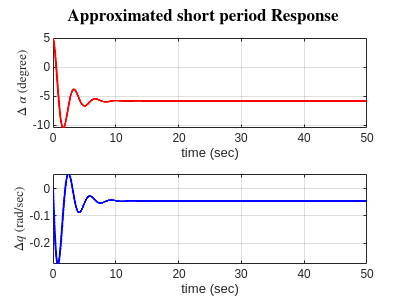

U_sp_apx=[5*pi/180*ones(size(time_SP));0 *ones(size(time_SP))];
x0=[5*pi/180*U0;0];
[Y_sp_apx,T_sp_apx,X_sp_apx]=lsim(SS_sp,U_sp_apx,time_SP,x0);
%Response of Approximated short period
figure (1)
sgtitle('\bf Approximated short period Response','interpreter','latex')
subplot(2,1,1)
plot(T_sp_apx,X_sp_apx(:,1)*180/U0/pi,"LineWidth",1.5,"Color",'R')
ylabel('$\Delta $ $\alpha $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(2,1,2)
plot(T_sp_apx,X_sp_apx(:,2),"LineWidth",1.5,"Color",'B')
ylabel('$\Delta q$ (rad/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on

### Long Period

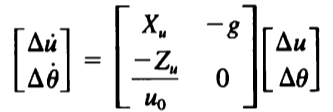

A_longitudinal_lp = [A_longitudinal(1,1),A_longitudinal(1,4);-ZU/U0 ,0]

A_longitudinal_lp =    -0.0017  -31.9342
    0.0001         0


B_longitudinal_lp = [B_longitudinal(1,1),B_longitudinal(1,2);B_longitudinal(4,1),B_longitudinal(4,2)]

B_longitudinal_lp =     2.6600    0.0008
         0         0


C_longitudinal_lp = eye(2)

C_longitudinal_lp =      1     0
     0     1


D_longitudinal_lp = zeros(2,2)

D_longitudinal_lp =      0     0
     0     0


SS_lp_apx = ss(A_longitudinal_lp,B_longitudinal_lp,C_longitudinal_lp,D_longitudinal_lp);
[eig_vectors_lp_apx,eig_values_lp_apx]= eig(A_longitudinal_lp)

eig_vectors_lp_apx =    1.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0000 - 0.0014i  -0.0000 + 0.0014i


eig_values_lp_apx =   -0.0008 + 0.0457i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0008 - 0.0457i


char_eq_lp_apx=poly([eig_values_lp_apx(1,1),eig_values_lp_apx(2,2)])

char_eq_lp_apx =     1.0000    0.0017    0.0021


Wn_longitudial_lp_apx = sqrt(char_eq_lp_apx(3))

Wn_longitudial_lp_apx = 0.0457

Zeta_longitudinal_lp_apx = char_eq_lp_apx(2)/2/Wn_longitudial_lp_apx

Zeta_longitudinal_lp_apx = 0.0184

Ts_longitudinal_lp_apx = 4/Zeta_longitudinal_lp_apx/Wn_longitudial_lp_apx

Ts_longitudinal_lp_apx = 4.7619e+03

Wd_longitudial_lp_apx = Wn_longitudial_lp_apx*sqrt(1-Zeta_longitudinal_lp_apx^2)

Wd_longitudial_lp_apx = 0.0457

OS_longitudial_lp_apx=exp(-Zeta_longitudinal_lp_apx*pi/(sqrt(1-Zeta_longitudinal_lp_apx^2)))

OS_longitudial_lp_apx = 0.9439

Approximated_long_period_charc=table(Wn_longitudial_lp_apx,Wd_longitudial_lp_apx,Zeta_longitudinal_lp_apx,Ts_longitudinal_lp_apx,OS_longitudial_lp_apx)

Approximated_long_period_charc = 1×5 table
    Wn_longitudial_lp_apx    Wd_longitudial_lp_apx    Zeta_longitudinal_lp_apx    Ts_longitudinal_lp_apx    OS_longitudial_lp_apx
    _____________________    _____________________    ________________________    ______________________    _____________________

          0.045683                 0.045676                   0.018387                    4761.9                   0.94386       


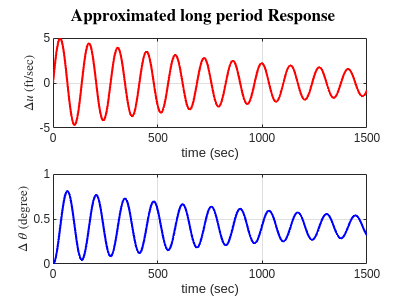

U_lp_apx=[5*pi/180*ones(size(time_LP));0*ones(size(time_LP))];
x0=[0;0];
[Y_lp_apx,T_lp_apx,X_lp_apx]=lsim(SS_lp_apx,U_lp_apx,time_LP,x0);
%Response of Approxim ated long period
figure (2)
sgtitle('\bf Approximated long period Response','interpreter','latex')
subplot(2,1,1)
plot(T_lp_apx,X_lp_apx(:,1),"LineWidth",1.5,"Color",'R')
ylabel('$\Delta u$ (ft/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(2,1,2)
plot(T_lp_apx,X_lp_apx(:,2)*180/pi,"LineWidth",1.5,"Color",'B')
ylabel('$\Delta $ $\theta $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on

# ***Linearized***

## Eigenvalues and Eigenvectors of Longitudinal Flight Dynamics

[e_vectors_longitudinal,e_values_longitudinal]= eig(A_longitudinal)

e_vectors_longitudinal =    0.1085 - 0.0264i   0.1085 + 0.0264i  -0.9926 + 0.0000i  -0.9926 + 0.0000i
  -0.9937 + 0.0000i  -0.9937 + 0.0000i  -0.1217 + 0.0022i  -0.1217 - 0.0022i
   0.0000 - 0.0030i   0.0000 + 0.0030i  -0.0002 + 0.0000i  -0.0002 - 0.0000i
  -0.0015 + 0.0004i  -0.0015 - 0.0004i   0.0001 + 0.0022i   0.0001 - 0.0022i


e_values_longitudinal =   -0.4989 + 1.8663i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.4989 - 1.8663i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0034 + 0.0708i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0034 - 0.0708i


Longitudinal_ss = ss(A_longitudinal,B_longitudinal,C_longitudinal,D_longitudinal)


Longitudinal_ss =
 
  A = 
              x1         x2         x3         x4
   x1   -0.00168     0.0498     -76.66     -31.93
   x2    -0.0408     -0.475      624.3     -3.921
   x3  0.0007567  -0.005497     -0.528  0.0009293
   x4          0          0          1          0
 
  B = 
              u1         u2
   x1       2.66   0.000842
   x2      -21.7          0
   x3     -4.265  -6.04e-06
   x4          0          0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


Longitudinal_TF = tf(Longitudinal_ss)


Longitudinal_TF =
 
  From input 1 to output...
             2.66 s^3 + 328.5 s^2 + 159 s + 61.66
   1:  -------------------------------------------------
       s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
            -21.7 s^3 - 2674 s^2 - 1.148 s - 6.061
   2:  -------------------------------------------------
       s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
        -4.265 s^3 - 1.912 s^2 - 0.01113 s - 2.589e-19
   3:  -------------------------------------------------
       s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
                -4.265 s^2 - 1.912 s - 0.01113
   4:  -------------------------------------------------
       s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
  From input 2 to output...
       0.000842 s^3 + 0.001307 s^2 + 0.003325 s + 7.428e-05
   1:  ----------------------------------------------------
        s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
            -0.003805 s^2 + 0.0003781 s - 1.03e-05
   2:  ------------------

[e_vectors_sp,e_values_sp]= eig(A_longitudinal_sp)

e_vectors_sp =    1.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0000 + 0.0030i  -0.0000 - 0.0030i


e_values_sp =   -0.5015 + 1.8524i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5015 - 1.8524i


[e_vectors_lp,e_values_lp]= eig(A_longitudinal_lp)

e_vectors_lp =    1.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0000 - 0.0014i  -0.0000 + 0.0014i


e_values_lp =   -0.0008 + 0.0457i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0008 - 0.0457i


## **Period**

U_LP_L=[5*pi/180*ones(size(time_LP));0*ones(size(time_LP))]; % Inputs matrix u (delta rudder = 5 degrees , delta thrust = 0)
U_SP_L=[5*pi/180*ones(size(time_SP));0*ones(size(time_SP))]; % Inputs matrix u (delta rudder = 5 degrees , delta thrust = 0)
x0=[0;5*pi/ 180*U0;0;0];                                   % Initial disturbance (alpha=5)
[Y_lpl,T_lpl,X_lpl]=lsim(Longitudinal_ss,U_LP_L,time_LP,x0);         % simulation for linearized longitudinal equation i n large time range
[Y_spl,T_spl,X_spl]=lsim(Longitudinal_ss,U_SP_L ,time_SP,x0);        % simulation for linearized longitudinal equation i n small time range


### Linear Model Longitudinal Elevator TFs

u_de = Longitudinal_TF(1,1)


u_de =
 
        2.66 s^3 + 328.5 s^2 + 159 s + 61.66
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


w_de = Longitudinal_TF(2,1)


w_de =
 
       -21.7 s^3 - 2674 s^2 - 1.148 s - 6.061
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


q_de = Longitudinal_TF(3,1)


q_de =
 
   -4.265 s^3 - 1.912 s^2 - 0.01113 s - 2.589e-19
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


theta_de = Longitudinal_TF(4,1)


theta_de =
 
           -4.265 s^2 - 1.912 s - 0.01113
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


### Linear Model Longitudinal Thrustor TFs

u_dth = Longitudinal_TF(1,2)


u_dth =
 
  0.000842 s^3 + 0.001307 s^2 + 0.003325 s + 7.428e-05
  ----------------------------------------------------
   s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


w_dth = Longitudinal_TF(2,2)


w_dth =
 
       -0.003805 s^2 + 0.0003781 s - 1.03e-05
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


q_dth = Longitudinal_TF(3,2)


q_dth =
 
  -6.04e-06 s^3 - 2.242e-06 s^2 + 4.744e-07 s + 2.896e-25
  -------------------------------------------------------
     s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


theta_th = Longitudinal_TF(4,2)


theta_th =
 
       -6.04e-06 s^2 - 2.242e-06 s + 4.744e-07
  -------------------------------------------------
  s^4 + 1.005 s^3 + 3.744 s^2 + 0.03064 s + 0.01875
 
Continuous-time transfer function.
Model Properties


## **Obtaining transfer functions for longitudinal approx. model**

%Extract Long Period Mode Approximated model transfer functions
SS_longitudinal_lp = ss(A_longitudinal_lp,B_longitudinal_lp,C_longitudinal_lp,D_longitudinal_lp);
TF_longitudinal_lp = tf(SS_longitudinal_lp);
[Long_Period_u_de] = TF_longitudinal_lp(1,1)


Long_Period_u_de =
 
            2.66 s
  --------------------------
  s^2 + 0.00168 s + 0.002087
 
Continuous-time transfer function.
Model Properties


[Long_Period_theta_de] = TF_longitudinal_lp(2,1)


Long_Period_theta_de =
 
          0.0001738
  --------------------------
  s^2 + 0.00168 s + 0.002087
 
Continuous-time transfer function.
Model Properties


[Long_Period_u_dT] = TF_longitudinal_lp(1,2)


Long_Period_u_dT =
 
          0.000842 s
  --------------------------
  s^2 + 0.00168 s + 0.002087
 
Continuous-time transfer function.
Model Properties


[Long_Period_theta_dT] = TF_longitudinal_lp(2,2)


Long_Period_theta_dT =
 
          5.503e-08
  --------------------------
  s^2 + 0.00168 s + 0.002087
 
Continuous-time transfer function.
Model Properties



%Extract Short Period Mode Approximated model transfer functions
SS_longitudinal_sp = ss(A_longitudinal_sp,B_longitudinal_sp,C_longitudinal_sp,D_longitudinal_sp);
TF_longitudinal_sp = tf(SS_longitudinal_sp);
[~,Short_Period_w_de] = TF_longitudinal_sp(1,1); 

Error using  () 
Too many output arguments.

[~,Short_Period_q_de] = TF_longitudinal_sp(2,1); 
[~,Long_Period_w_dT] = TF_longitudinal_sp(2,1); 
[~,Long_Period_q_dT] = TF_longitudinal_sp(2,2); 

## Longitudinal Approximations

Natural frequency, settling time, damped frequency and damping ratio.

### Phugoid

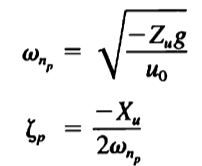

char_eq_longitudinal_lp= poly([e_values_longitudinal(3,3),e_values_longitudinal(4,4)])
Wn_logintudinal_lp = sqrt(-1*g*ZU/U0)
Zeta_longitudinal_lp = -1*XU/2/Wn_logintudinal_lp
Ts_longitudinal_lp = 4/Zeta_longitudinal_lp/Wn_logintudinal_lp
Wd_longitudinal_lp = Wn_logintudinal_lp*sqrt(1-Zeta_longitudinal_lp^2)
OS_longitudinal_lp = Zeta_longitudinal_lp*pi/(sqrt(1-Zeta_longitudinal_lp^2))
linear_longitudinal_period_charc=table(Wn_logintudinal_lp,Wd_longitudinal_lp,Zeta_longitudinal_lp,Ts_longitudinal_lp,OS_longitudinal_lp)

## ***Response of linearized longitudinal model in longer time interval***

figure(3)
sgtitle('\bf Linearized model Response over long time interval','interpreter','latex')
subplot(4,1,1)
plot(T_lpl,X_lpl(:,1),"LineWidth",1.5,"Color",'R')
ylabel('$\Delta u$ (ft/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,2)
plot(T_lpl,X_lpl(:,2)*180/U0/pi,"LineWidth",1.5,"Color",'B')
ylabel('$\Delta $ $\alpha $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,3)
plot(T_lpl,X_lpl(:,3),"LineWidth",1.5,"Color",'Y')
ylabel('$\Delta q$ (rad/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,4)
plot(T_lpl,X_lpl(:,4)*180/U0/pi,"LineWidth",1.5,"Color",'G')
ylabel('$\Delta $ $\theta $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on

### Short Period

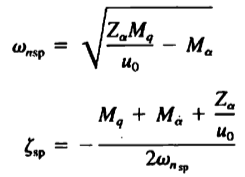

Z_alpha = U0*ZW;
M_alpha = U0* MW;
M_alpha_D = U0 * MWD;
char_eq_spl=poly([e_values_longitudinal(1,1),e_values_longitudinal(2,2)])
Wn_longitudial_sp = sqrt((Z_alpha*MQ/U0)-M_alpha)
Zeta_longitudinal_sp = -1*((MQ+M_alpha_D+(Z_alpha/U0))/2/Wn_longitudial_sp)
Ts_longitudinal_sp = 4/Zeta_longitudinal_sp/Wn_longitudial_sp
Wd_longitudial_sp = Wn_longitudial_sp*sqrt(1-Zeta_longitudinal_sp^2)
OS_longitudial_sp=exp( -Zeta_longitudinal_sp*pi/(sqrt(1-Zeta_longitudinal_sp^2)))
linear_short_period_charc=table(Wn_longitudial_sp,Wd_longitudial_sp,Zeta_longitudinal_sp,Ts_longitudinal_sp,OS_longitudial_sp)

## *** Respone of linearized longitudinal model in shorter time interval***

figure(4)
sgtitle('\bf Linearized model Response over short time interval','interpreter','latex')
subplot(4,1,1)
plot(T_spl,X_spl(:,1),"LineWidth",1.5,"Color",'R')
ylabel('$\Delta u$ (ft/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,2)
plot(T_spl,X_spl(:,2)*180/U0/pi,"LineWidth",1.5,"Color",'B')
ylabel('$\Delta $ $\alpha $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,3)
plot(T_spl,X_spl(:,3),"LineWidth",1.5,"Color",'Y')
ylabel('$\Delta q$ (rad/sec)','Interpreter','latex')
xlabel("time (sec)")
grid on
subplot(4,1,4)
plot(T_spl,X_spl(:,4)*180/U0/pi,"LineWidth",1.5,"Color",'G')
ylabel('$\Delta $ $\theta $ (degree)','Interpreter','latex')
xlabel("time (sec)")
grid on

### ***Comparisons***

%Errors short period
error_sp_wn=abs(Wn_longitudial_sp-Wn_longitudial_sp_apx)/Wn_longitudial_sp*100;
error_sp_wd=abs(Wd_longitudial_sp-Wd_longitudial_sp_apx)/Wd_longitudial_sp*100;
error_sp_zeta=abs(Zeta_longitudinal_sp-Zeta_longitudinal_sp_apx)/Zeta_longitudinal_sp*100;
error_sp_Ts=abs(Ts_longitudinal_sp-Ts_longitudinal_sp_apx)/Ts_longitudinal_sp*100;
error_sp_OS=abs(OS_longitudial_sp-OS_longitudial_sp_apx)/OS_longitudial_sp*100;
errors_sp_table=table(error_sp_wn,error_sp_wd,error_sp_zeta,error_sp_Ts,error_sp_OS)
%Errors long period
error_lp_wn=abs(Wn_logintudinal_lp-Wn_longitudial_lp_apx)/Wn_logintudinal_lp*100;
error_lp_wd=abs(Wd_longitudinal_lp-Wd_longitudial_lp_apx)/Wd_longitudinal_lp*100;
error_lp_zeta=abs(Zeta_longitudinal_lp-Zeta_longitudinal_lp_apx)/Zeta_longitudinal_lp*100;
error_lp_Ts=abs(Ts_longitudinal_lp-Ts_longitudinal_lp_apx)/Ts_longitudinal_lp*100;
error_lp_OS=abs(OS_longitudinal_lp-OS_longitudial_lp_apx)/OS_longitudinal_lp*100;
errors_lp_table=table(error_lp_wn,error_lp_wd,error_lp_zeta,error_lp_Ts,error_lp_OS)

% Response comparison
% U comparison
figure (5)
plot(T_lpl,X_lpl(:,1),"LineWidth",1.5,"Color",'R')
hold on
plot(T_sp_apx,X_sp_apx(:,1),"LineWidth",1.5,"Color",'G')
hold off
sgtitle('\bf Delta U Comparison','interpreter','latex')
ylabel('$\ Delta U$ (ft/sec)','interprete','latex')
xlabel("time(sec)")
legend('Linearized model','Approximated long period model')
grid on

%Theta Comparison
figure (6)
plot(T_lpl,X_lpl(:,4)*180/pi,"LineWidth",1.5,"Color",'R')
hold on
plot(T_sp_apx,X_sp_apx(:,2)*180/pi,"LineWidth",1.5,"Color",'G')
hold off
sgtitle('\bf Theta Comparison','interpreter','latex')
ylabel('$\ Delta $ $\theta $ (degree)','interprete','latex')
xlabel("time(sec)")
legend('Linearized model','Approximated long period model')
grid on

%Alpha Comparison
figure (7)
plot(T_spl,X_spl(:,2)*180/pi,"LineWidth",1.5,"Color",'R')
hold on
plot(T_sp_apx,X_sp_apx(:,1)*180/pi,"LineWidth",1.5,"Color",'G')
hold off
sgtitle('\bf Alpha Comparison','interpreter','latex')
ylabel('$\ Delta $ $\alpha $ (degree)','interprete','latex')
xlabel("time(sec)")
legend('Linearized model','Approximated long period model')
grid on

% q Comparison
figure (8)
plot(T_spl,X_spl(:,3),"LineWidth",1.5,"Color",'R')
hold on
plot(T_sp_apx,X_sp_apx(:,2),"LineWidth",1.5,"Color",'G')
hold off
sgtitle('\bf q Comparison','interpreter','latex')
ylabel('$\ Delta q$ (rad/sec)','interprete','latex')
xlabel("time(sec)")
legend('Linearized model','Approximated long period model')
grid on

## Lateral

G=1/(1-(Ixz^2/(Ixx*Izz)));

Trans_Mat=[G G*Ixz/Ixx;G*Ixz/Izz G];
Trans_Mat_inv=inv(Trans_Mat);


YP = 0;
YR = 0;
YV = SD_Lat_dash(1);
YB_DASH = SD_Lat_dash(2);
LB_DASH = SD_Lat_dash(3);
NB_DASH = SD_Lat_dash(4);
LP_DASH = SD_Lat_dash(5);
NP_DASH = SD_Lat_dash(6);
LR_DASH = SD_Lat_dash(7);
NR_DASH = SD_Lat_dash(8);
YDA = SD_Lat_dash(9);
YDR = SD_Lat_dash(10);

YDA_Normal = YDA*Vto;
YDR_Normal = YDR*Vto;

LDA = SD_Lat_dash(11);
NDA = SD_Lat_dash(12);
LDR = SD_Lat_dash(13);
NDR = SD_Lat_dash(14);

LN_v = Trans_Mat_inv*[LB_DASH;NB_DASH]./Vto;
LN_p = Trans_Mat_inv*[LP_DASH;NP_DASH];
LN_r = Trans_Mat_inv*[LR_DASH;NP_DASH];
LN_dr =Trans_Mat_inv*[LDR;NDR];
LN_da =Trans_Mat_inv*[LDA;NDA];

L_v_dash = (LN_v(1) + Ixz*LN_v(2)/Ixx)/G;
N_v_dash = (LN_v(2) + Ixz*LN_v(1)/Izz)/G;

SD_Lat = [YV LN_v(1) LN_v(2) LN_p(1) LN_p(2) LN_r(1) LN_r(2) YDA_Normal YDR_Normal LN_da(1) LN_da(2) LN_dr(1) LN_dr(2)]';

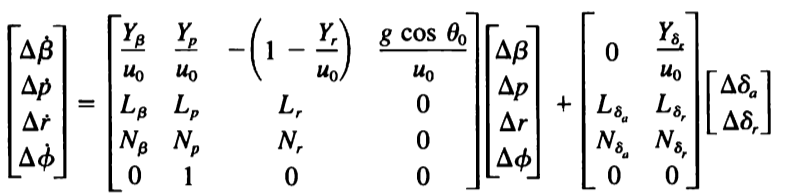

%linearized model w.r.t beta

A_lateral = [YV , (W0+YP)/Vto , (-U0+YR)/Vto , g*cos(theta0)/Vto , 0;...
        LB_DASH , LP_DASH , LR_DASH , 0 , 0;...
        NB_DASH , NP_DASH , NR_DASH , 0 , 0;...
        0 , 1 , tan(theta0) , 0 , 0;...
        0 , 0 , 1/cos(theta0) ,0 ,0]

B_lateral = [YDA , YDR;...
         LDA , LDR;...
         NDA , NDR;...
         0 , 0;...
         0 , 0]
     
C_lateral=eye(5)
D_lateral=zeros(5,2)

%linearized model w.r.t v

A_lateral_v = [YV , (W0+YP) , (-U0+YR) , g*cos(theta0) , 0;...
        LB_DASH , LP_DASH , LR_DASH , 0 , 0;...
        NB_DASH , NP_DASH , NR_DASH , 0 , 0;...
        0 , 1 , tan(theta0) , 0 , 0;...
        0 , 0 , 1/cos(theta0) ,0 ,0]

B_lateral_v = [YDA , YDR;...
         LDA , LDR;...
         NDA , NDR;...
         0 , 0;...
         0 , 0]
     



## Modes Approximation

### Roll Mode

A_lateral_R = LP_DASH
B_lateral_R = LR_DASH
       
C_lateral_R = eye(1)
D_lateral_R = zeros(1,1)

### Dutch Mode

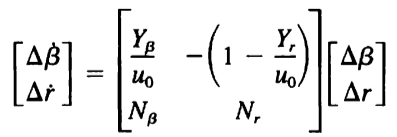

A_lateral_D = [YB_DASH/U0 ,-1*(1-YR/U0) %- tan(theta0)*(YP+W0)/U0
    ; NB_DASH , NR_DASH]
B_lateral_D = [LDA , LDR;NDA , NDR;]
       
C_lat_D = eye(2)
D_lat_D = zeros(2,2)

### Spiral Mode

A_lateral_S = (NR_DASH*LB_DASH -LR_DASH*NB_DASH)/LB_DASH
B_lateral_S = 0
       
C_lateral_S = eye(1)
D_lateral_S = zeros(1,1)

## **Obtaining transfer functions**

%state space model
Linearized_Lateral_Syetem = ss(A_lateral, B_lateral, C_lateral, D_lateral);
Roll_Mode_System = ss(A_lateral_R, B_lateral_R, C_lateral_R, D_lateral_R);
Dutch_Mode_System = ss(A_lateral_D, B_lateral_D, C_lat_D, D_lat_D);
Spiral_Mode_Syatem = ss(A_lateral_S, B_lateral_S, C_lateral_S, D_lateral_S);

%Extraction of TFs of the linearized model
[~, Linearized_Lateral_B_Dr ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,2,1);
[~, Linearized_Lateral_p_Dr ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,2,2);
[~, Linearized_Lateral_r_Dr ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,2,3);
[~, Linearized_Lateral_phi_Dr ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,2,4);
[~, Linearized_Lateral_psi_Dr ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,2,5);
[~, Linearized_Lateral_v_Dr ] = ss2tf(A_lateral_v, B_lateral_v, C_lateral, D_lateral,2,1);

[~, Linearized_Lateral_v_Da ] = ss2tf(A_lateral_v, B_lateral_v, C_lateral, D_lateral,1,1);
[~, Linearized_Lateral_B_Da ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,1,1);
[~, Linearized_Lateral_p_Da ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,1,2);
[~, Linearized_Lateral_r_Da ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,1,3);
[~, Linearized_Lateral_phi_Da ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,1,4);
[~, Linearized_Lateral_psi_Da ] = ss2tf(A_lateral, B_lateral, C_lateral, D_lateral,1,5);


%Extract roll mode approx. model TF
[~, Roll_p_da] = ss2tf(A_lateral_R, B_lateral_R, C_lateral_R, D_lateral_R,1,1);

%Extract Dutch mode appreox. model TF
[~, Dutch_Beta_Da] = ss2tf(A_lateral_D, B_lateral_D, C_lat_D, D_lat_D,1,1);
[~, Dutch_r_Da] = ss2tf(A_lateral_D, B_lateral_D, C_lat_D, D_lat_D,1,2);
[~, Dutch_beta_Dr] = ss2tf(A_lateral_D, B_lateral_D, C_lat_D, D_lat_D,2,1);
[~, Dutch_r_Dr] = ss2tf(A_lateral_D, B_lateral_D, C_lat_D, D_lat_D,2,2);

%Extract spiral mode approx. model TF

[~,Spiral_p_Da]   = ss2tf(A_lateral_S,B_lateral_S,C_lateral_S,D_lateral_S,1,1); 



## Eigen Values and Eigen Vectors for Lateral Flight Dynamics

[e_vectors_lat,e_values_lat]= eig(A_lateral)

Lateral_ss = ss(A_lateral,B_lateral,C_lateral,D_lateral)
Lateral_TF = tf(Lateral_ss)

[e_vectors_DR_approximation,e_values_DR_approximation]= eig(A_lateral_D)

### Spiral Approximation

eig_Value_Spiral_approximation = (LB_DASH*NR_DASH-LR_DASH*NB_DASH)/LB_DASH

### Roll Approximation

eig_Value_Roll_approximation = LP_DASH

### Dutch Roll Approximation

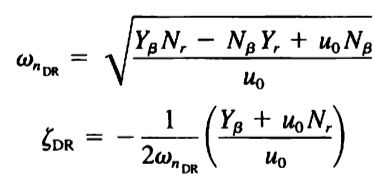

Wn_DR_approximation = sqrt((YB_DASH*NR_DASH-NB_DASH*YR+U0*NB_DASH)/U0)
Zeta_DR_approximation = -1*((YB_DASH+U0*NR_DASH)/U0)/2/Wn_DR_approximation